# ANOVA Example

Andrew Brown

GEEN 3853

10/23/2020

## INTRODUCTION

We will investigate two scenarios with this data: 1) overall pay comparison of men and women faculty at Houston College of Medicine, and 2) pay comparison of men and women assistant professors.

The first scenario lets us know if there is an overall gender pay gap, but as Dr. D’Andrea Tyson explains in the World Economic Forum article, there can be many confounding variables that can contribute to this gender gap.  For example, faculty can be associate professor and full professors for many years, so it could be that one group has been faculty members for longer, and typically faculty earn higher salaries as they earn more experience.  Thus, in the second scenario, we only look at assistant professors because assistant professors have less variance in their years of experience—you are usually only an assistant professor for less than seven years.  We are trying to control for the variable of years of experience to better understand the gender pay gap.

### Research Questions

- To what extent did the salaries of men and women faculty at Houston College of Medicine differ in 1995?

- To what extent did the salaries of men and women assistant professors at Houston College of Medicine differ in 1995?

## PREP WORKSPACE

clear all
close all
clc

## Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 26-Oct-2020 14:52:42

## Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 10);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["ID", "Dept", "Gender", "Clin", "Cert", "Prate", "Exper", "Rank", "Sal94", "Sal95"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
raw = readtable("C:\Users\andre\OneDrive\Documents\MATLAB\GEEN 3583\PayGap.csv", opts);
raw(1:5,:)

ans = 5×10 table
    ID    Dept    Gender    Clin    Cert    Prate    Exper    Rank      Sal94        Sal95   
    __    ____    ______    ____    ____    _____    _____    ____    _________    __________

    1      1        1        0       0       7.4       9       3          77836         84612
    2      1        1        0       0       6.7      10       2          69994         78497
    3      1        1        0       0       8.1       6       1          62872         67756
    4      1        1        1       1       5.1      27       3      1.552e+05    1.7322e+05
    5      1        1        0       0         7      10       3          8926

## Clear temporary variables

clear opts

## CLEAN AND SUBSET THE DATA

View the dataset and perform necessary cleanup.

%We want some rows and columns.
rawGenderArray = table2array(raw(:,3));
rawSalaryArray = table2array(raw(:,10));
rawRankArray = table2array(raw(:,8));
rawDataArray = cat(2,rawGenderArray,rawRankArray,rawSalaryArray);

%Get Salary information about all of the needed groups into individual
%arrays and one array in long format.

numM = 0;
numF = 0;
numAsstM = 0;
numAsstF = 0;
numAssocM = 0;
numAssocF = 0;
numPM = 0;
numPF = 0;

men = zeros(155,1);       %Salaries for All Males
women = zeros(106,1);     %Salaries for All Females
asstMen = zeros(43,1);    %Salaries for All Assistant Professors who are Males
asstWomen = zeros(69,1);  %Salaries for All Assistant Professors who are Females
assocMen = zeros(43,1);   %Salaries for All Associate Professors who are Men
assocWomen = zeros(21,1); %Salaries for All Associate Professors who are Women
profMen = zeros(69,1);    %Salaries for All Full Professors who are Men
profWomen = zeros(16,1);  %Salaries for All Full Professors who are Women

for i = 1:261
    if rawDataArray(i,1) == 1
        numM = numM + 1;
        men(numM) = rawDataArray(i,3);
        if rawDataArray(i,2) == 1
            numAsstM = numAsstM + 1;
            asstMen(numAsstM) = rawDataArray(i,3);
        elseif rawDataArray(i,2) == 2
            numAssocM = numAssocM + 1;
            assocMen(numAssocM) = rawDataArray(i,3);
        elseif rawDataArray(i,2) == 3
            numPM = numPM + 1;
            profMen(numPM) = rawDataArray(i,3);
        end  
    else
        numF = numF + 1;
        women(numF) = rawDataArray(i,3);
        if rawDataArray(i,2) == 1
            numAsstF = numAsstF + 1;
            asstWomen(numAsstF) = rawDataArray(i,3);
        elseif rawDataArray(i,2) == 2
            numAssocF = numAssocF + 1;
            assocWomen(numAssocF) = rawDataArray(i,3);
        elseif rawDataArray(i,2) == 3
            numPF = numPF + 1;
            profWomen(numPF) = rawDataArray(i,3);
        end
    end
end

dataLong = cat(1,men,women,asstMen,asstWomen); %All salary data in long format
numsLong = cat(1,zeros(numM,1),ones(numF,1),2*ones(numAsstM,1),3*ones(numAsstF,1)); %Long format categorical nums

%Get max and mins
menExtremes = [min(men),max(men)];
womenExtremes = [min(women),max(women)];
asstMenExtremes = [min(asstMen),max(asstMen)];
asstWomenExtremes = [min(asstWomen),max(asstWomen)];


## DESCRIPTIVE STATISTICS - VISUAL

### Histograms

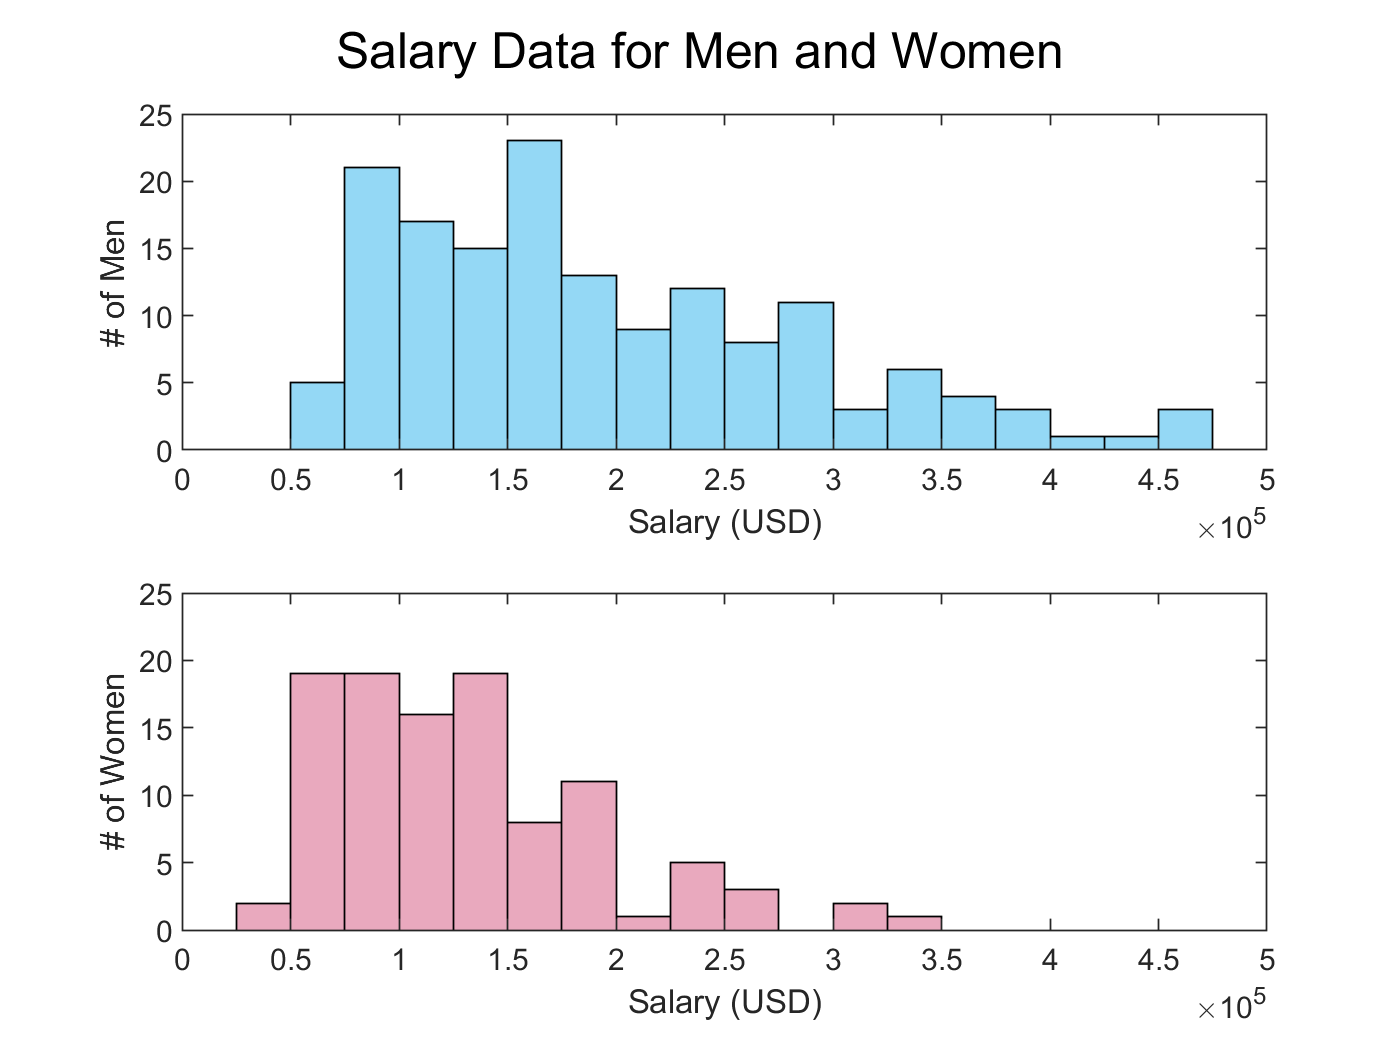

%Obtain the histogram plot of the dataset
figure
subplot(2,1,1)
histogram(men,'BinWidth',25000,'FaceColor','#4DBEEE')
xlabel("Salary (USD)")
ylabel("# of Men")
axis([0,500000,0,25])

subplot(2,1,2)
histogram(women,'BinWidth',25000,'FaceColor','#DB7093')
xlabel("Salary (USD)")
ylabel("# of Women")
axis([0,500000,0,25])

sgtitle("Salary Data for Men and Women")

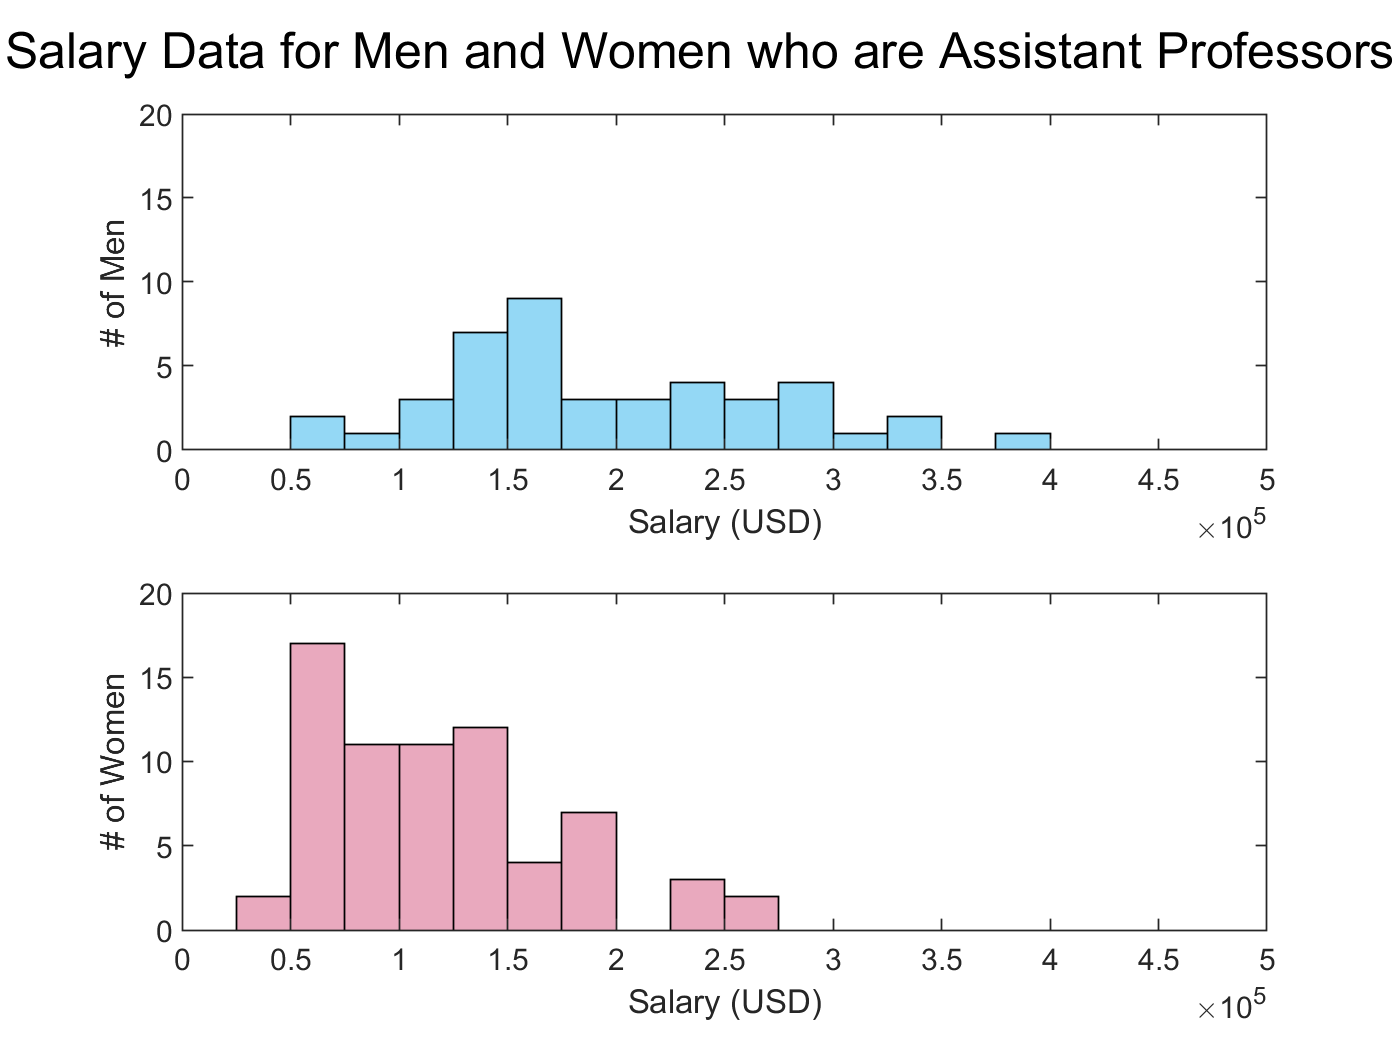

%Obtain the histogram plot of the dataset
figure
subplot(2,1,1)
histogram(asstMen,'BinWidth',25000,'FaceColor','#4DBEEE')
xlabel("Salary (USD)")
ylabel("# of Men")
axis([0,500000,0,20])


subplot(2,1,2)
histogram(asstWomen,'BinWidth',25000,'FaceColor','#DB7093')
xlabel("Salary (USD)")
ylabel("# of Women")
axis([0,500000,0,20])

sgtitle("Salary Data for Men and Women who are Assistant Professors")

### **Histograms for Each Level of Proffession**

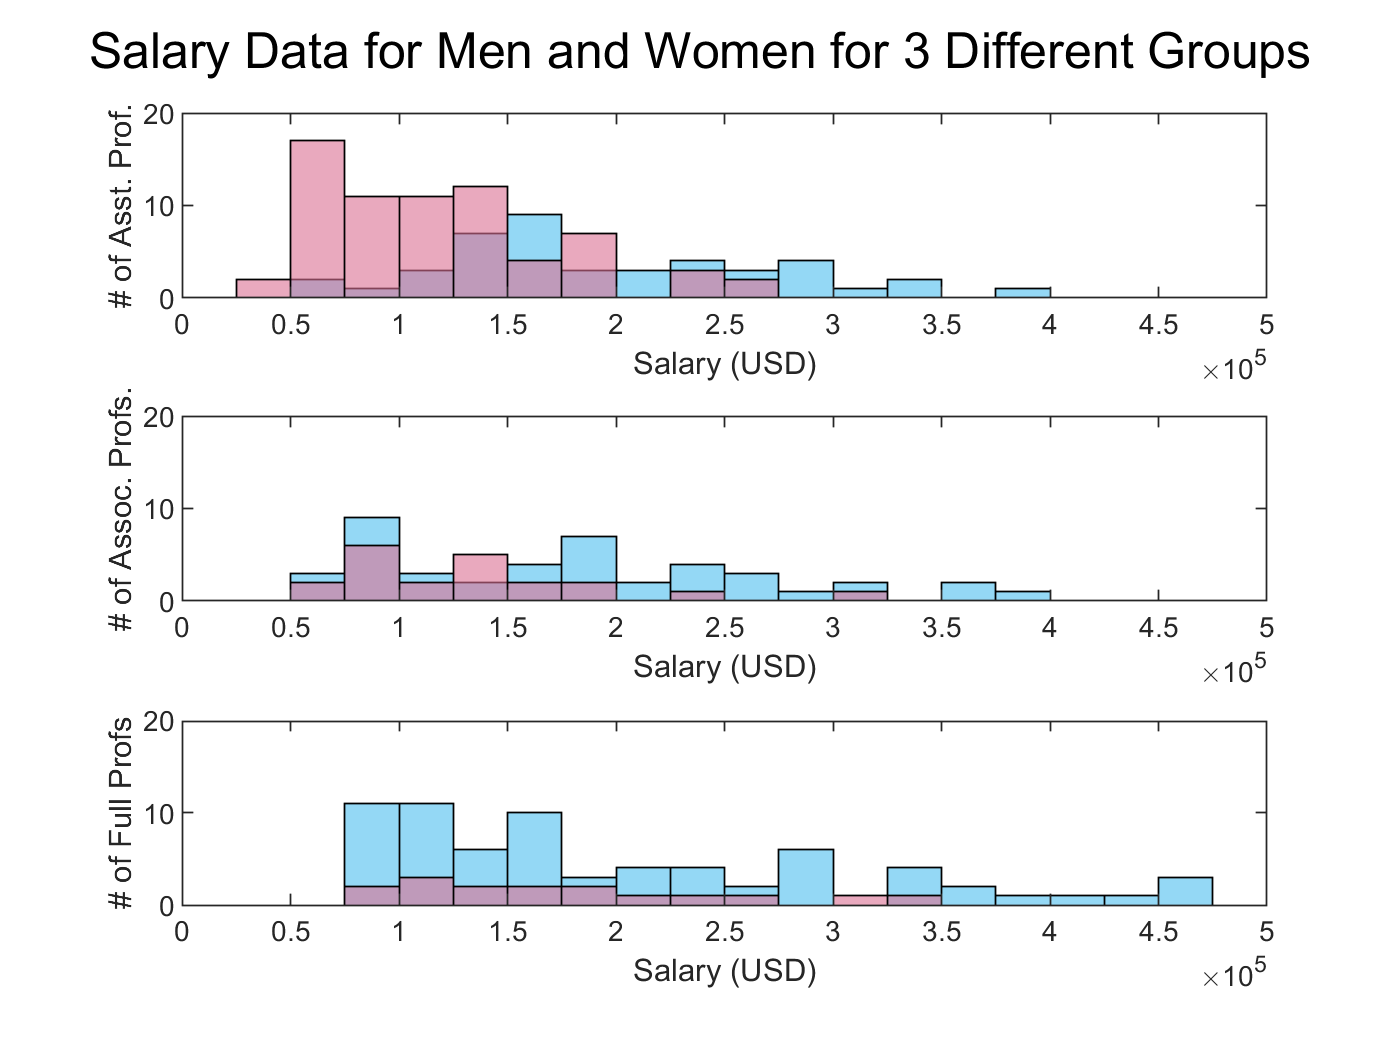

figure
subplot(3,1,1)

histogram(asstMen,'BinWidth',25000,'FaceColor','#4DBEEE')
hold on
histogram(asstWomen,'BinWidth',25000,'FaceColor','#DB7093')
xlabel("Salary (USD)")
ylabel("# of Asst. Prof.")
axis([0,500000,0,20])
hold off

subplot(3,1,2)
histogram(assocMen,'BinWidth',25000,'FaceColor','#4DBEEE')
hold on
histogram(assocWomen,'BinWidth',25000,'FaceColor','#DB7093')
xlabel("Salary (USD)")
ylabel("# of Assoc. Profs.")
axis([0,500000,0,20])
hold off

subplot(3,1,3)
histogram(profMen,'BinWidth',25000,'FaceColor','#4DBEEE')
hold on
histogram(profWomen,'BinWidth',25000,'FaceColor','#DB7093')
xlabel("Salary (USD)")
ylabel("# of Full Profs")
axis([0,500000,0,20])
hold off
sgtitle("Salary Data for Men and Women for 3 Different Groups")

**Take Aways:**

For all 3 data sets, it seems that the populations of men have means that are higher those of the populations of women. The variances for the populations of men also all seem to be bigger than the variancres for all the populations women.

### **Probability Density Function Plots**

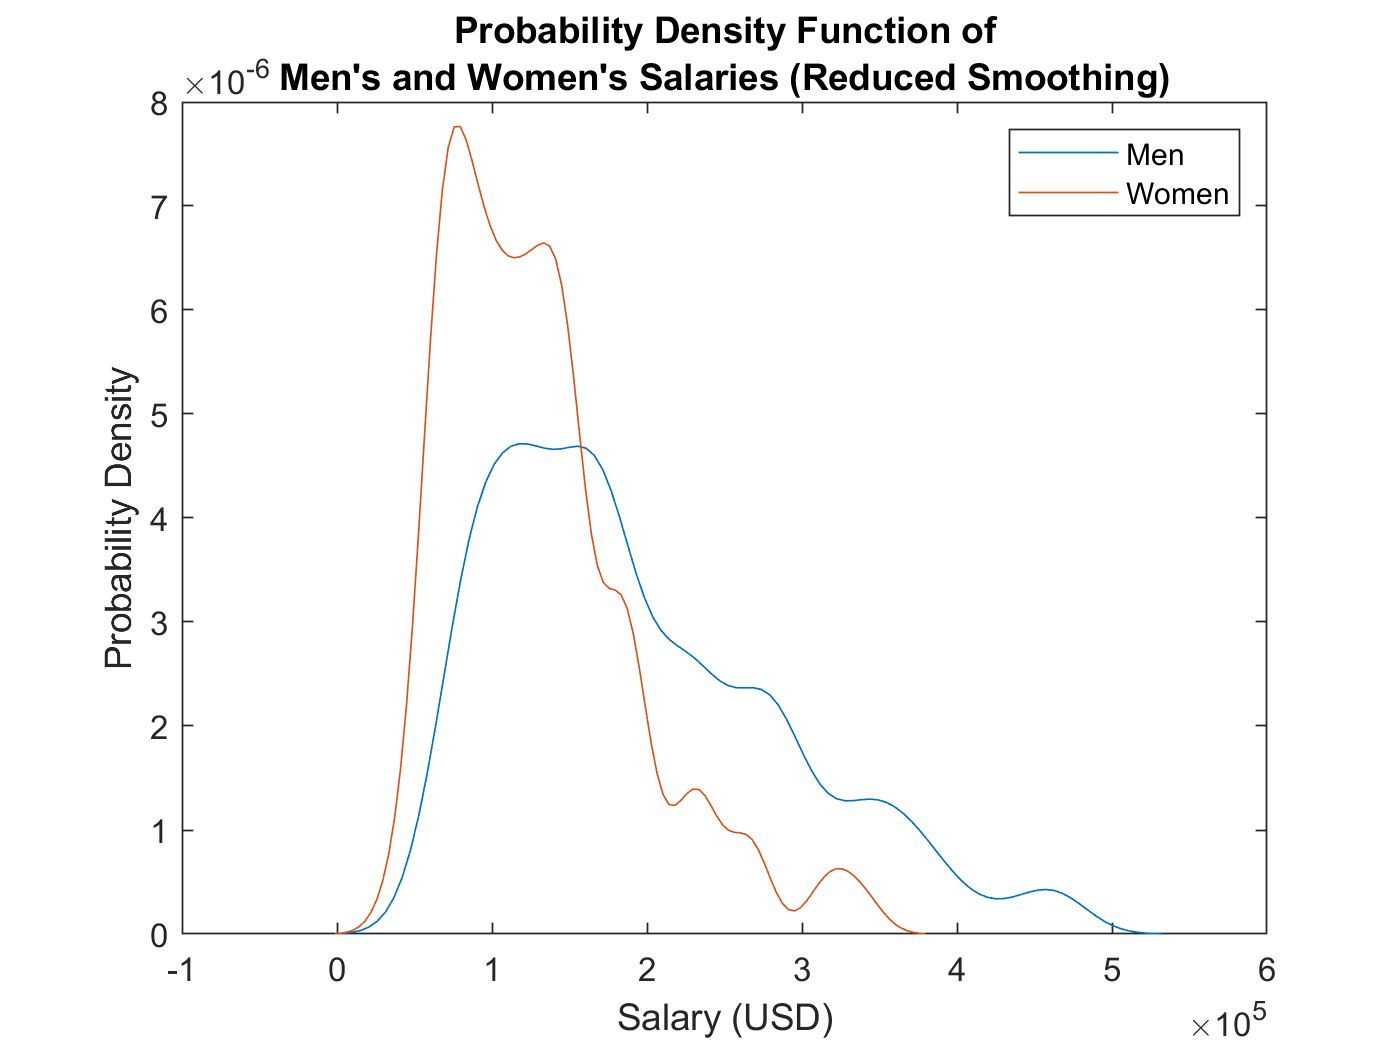

%'Bandwidth' adjusts how much filtering is applied: larger # = more
%filtering
figure
ksdensity(men,'function','pdf','Bandwidth',20000) % Default Bandwidth = 3.3964e+04
hold on
ksdensity(women,'function','pdf','Bandwidth',13333) % Default Bandwidth = 2.2484e+04
xlabel('Salary (USD)')
ylabel('Probability Density')
legend('Men','Women')
title("Probability Density Function of"+newline+"Men's and Women's Salaries (Reduced Smoothing)")
hold off

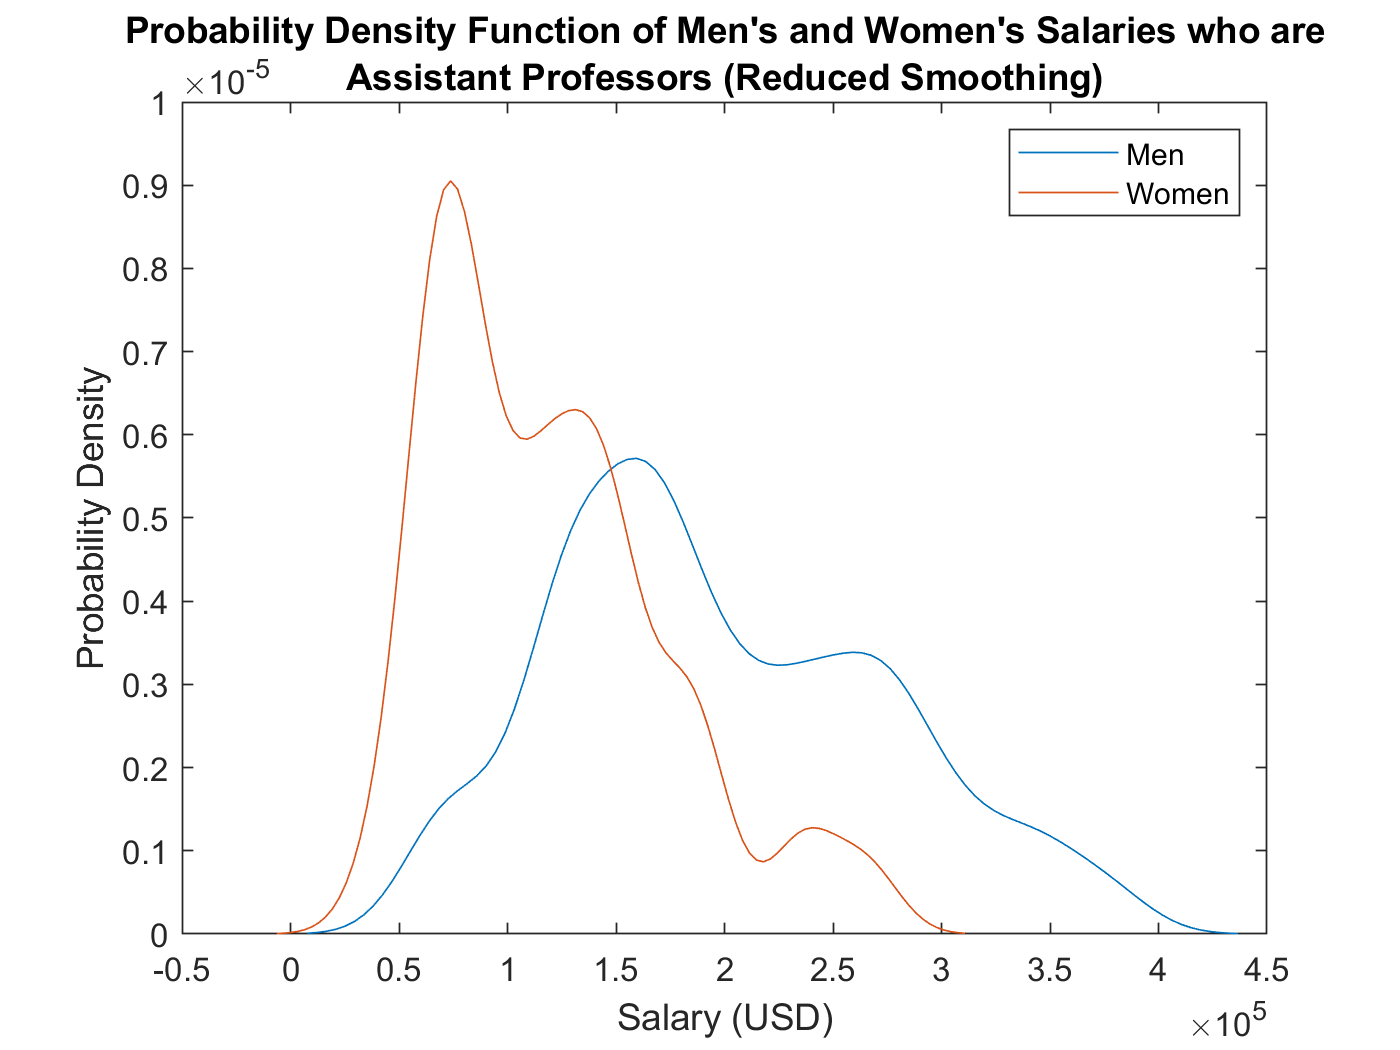

figure
ksdensity(asstMen,'function','pdf','Bandwidth',20000) % Default Bandwidth = 3.5319e+04
hold on
ksdensity(asstWomen,'function','pdf','Bandwidth',15000) % Default Bandwidth = 2.5972e+04
xlabel('Salary (USD)')
ylabel('Probability Density')
legend('Men','Women')
title("Probability Density Function of Men's and Women's Salaries who are"+newline+"Assistant Professors (Reduced Smoothing)")
hold off

**Take Aways: **

From the histograms and PDF plots, it seems that both male populations are skewed slightly more towards higher salaris than both women populations. It also seems that both male populations may have slightly larger variances in pay, but do not have lower pay. More statistical analysis will be needed test these hypotheses.

## Boxplots

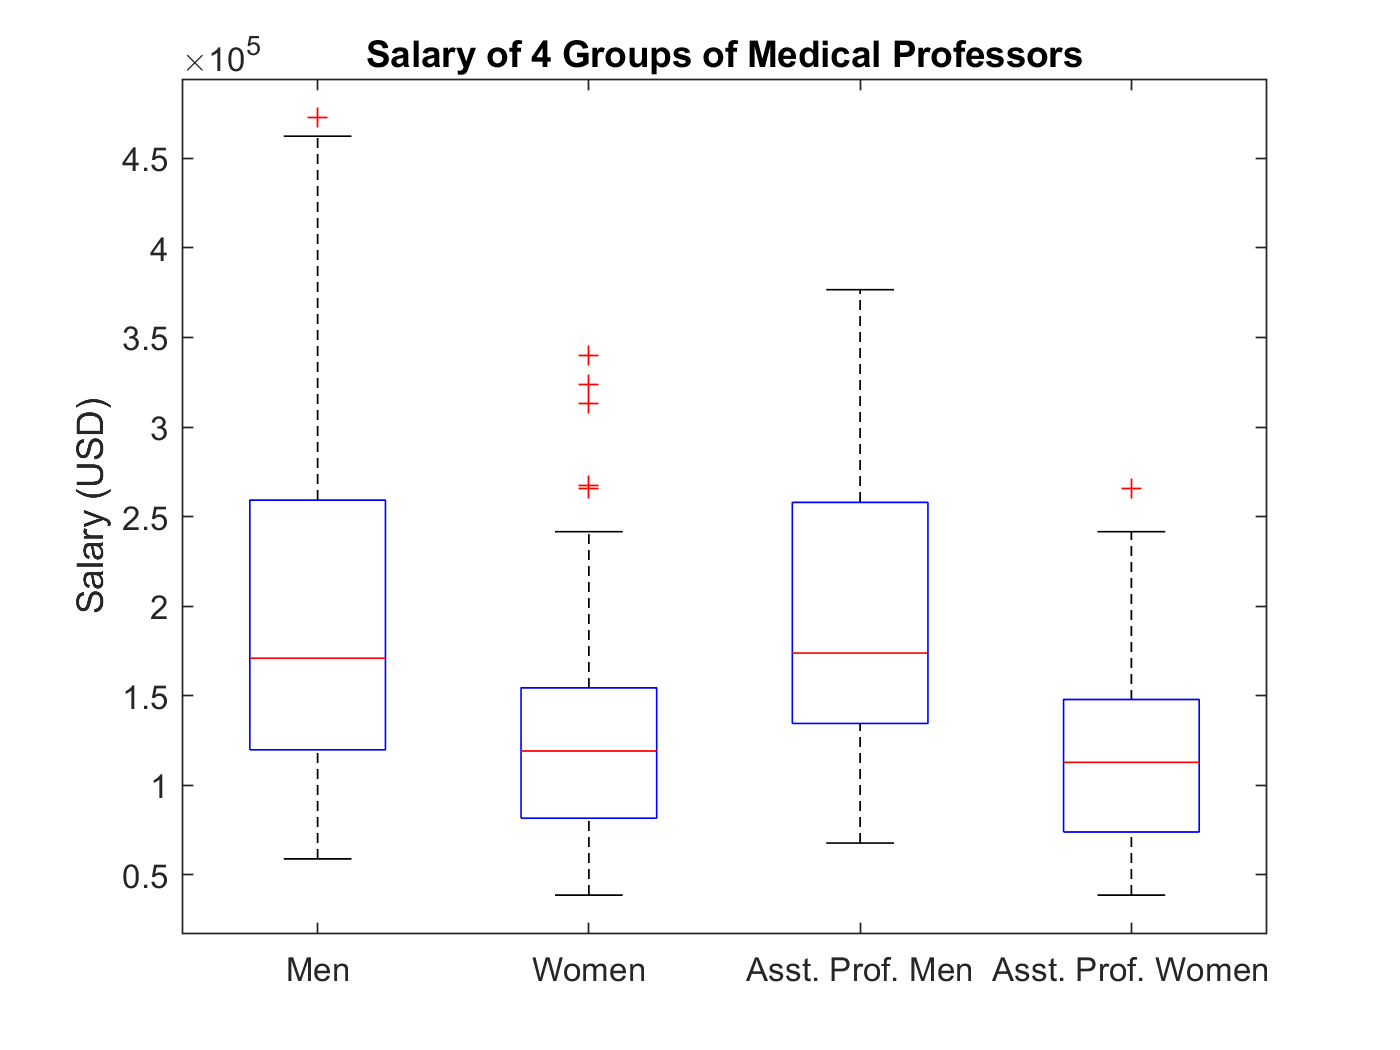

figure
boxplot(dataLong,numsLong,"Labels",{'Men','Women','Asst. Prof. Men','Asst. Prof. Women'})
ylabel ('Salary (USD)')
title('Salary of 4 Groups of Medical Professors')
hold off

**Take Aways:**

The box plot confirms the above hypotheses. It is clear from this plot that both populations of men have higher average salaries than both populations of women and have higher variance in pay, but never below the lowest paid women in either of the women populations. Statistical analysis must be preformed to ensure significance of these hypotheses made from the graphs.

## DESCRIPTIVE STATISTICS - NUMERIC

## Univariate

%Set up a results table
tMen = table();

tMen.Mean = mean(men)';
tMen.SD = std(men)';
tMen.Med = median(men)';
tMen.Max = max(men)';
tMen.Min = min(men)';
tMen.IQR = iqr(men)';

tWomen = table();

tWomen.Mean = mean(women)';
tWomen.SD = std(women)';
tWomen.Med = median(women)';
tWomen.Max = max(women)';
tWomen.Min = min(women)';
tWomen.IQR = iqr(women)';

tAsstMen = table();

tAsstMen.Mean = mean(asstMen)';
tAsstMen.SD = std(asstMen)';
tAsstMen.Med = median(asstMen)';
tAsstMen.Max = max(asstMen)';
tAsstMen.Min = min(asstMen)';
tAsstMen.IQR = iqr(asstMen)';

tAsstWomen = table();

tAsstWomen.Mean = mean(asstWomen)';
tAsstWomen.SD = std(asstWomen)';
tAsstWomen.Med = median(asstWomen)';
tAsstWomen.Max = max(asstWomen)';
tAsstWomen.Min = min(asstWomen)';
tAsstWomen.IQR = iqr(asstWomen)';

ds = vertcat(tMen,tWomen,tAsstMen,tAsstWomen);
ds.Properties.RowNames = {'Men','Women','Asst. Prof. Men','Asst. Prof. Women'};
ds

ds = 4×6 table
                            Mean        SD         Med           Max         Min        IQR    
                         __________    _____    __________    __________    _____    __________

    Men                  1.9491e+05    94903    1.7097e+05    4.7259e+05    58923    1.3937e+05
    Women                1.3088e+05    62035    1.1914e+05    3.3966e+05    38675         72771
    Asst. Prof. Men      1.9784e+05    77196    1.7384e+05    3.7665e+05    67756    1.2341e+05
    Asst. Prof. Women     1.198e+05    54124    1.1284e+05    2.6586e+05    38675         73965


**Take Aways: **

The descriptive univariate statistics confirm numerically our hypotheses from the visual statistics that both men populations make more on average than both women populations and have higher standard deviations (and therefore higher variances). Also, both men populations have higher median salaries, higher max salries, and higher minimum salaries than both women populations. The next section will find if these differences are statistically significant. 

### Bivariate

The most common bivariate statistic that we will utilize is the correlation coefficient.

This doesn't make sense to compute for this data/problem.

# INFERENTIAL STATISTICS

Our ultimate goal is to test the difference in means.  However, to do that, we need to first test the normality of the groups.  We also need to know if the groups have equal or unequal variance so that we know what t-test to use in our test of location.

## TEST OF NORMALITY

For a two-sample, independent test, we need to test the normality of each group.

Underlying Assumptions of the Test :

- The data are continuous.

- The data are from a sample that was randomly drawn from a process/population.

Method: Anderson-Darling and Normality Plot

Step 1 : (Note that a non-directional test is assumed.)

H0 :$\gamma$_3 = 0 and $\gamma$_4 = 0 for all groups

H1 : $\gamma$_3 $\not=$ 0 and $\gamma$_4 $\not=$ 0 for some/all groups

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make

alpha1 = 0.05

alpha1 = 0.0500

Step 3 : We will use the AD test statistic.

Step 4 : We will use the AD RSD

Step 5 : State the Critical Value for Rejecting the Null Hypothesis

    Quantitative: Reject H0 if any p-value < $\alpha$ 

Step 6 : Calculations

### Normality Plot & Anderson-Darling Statistic

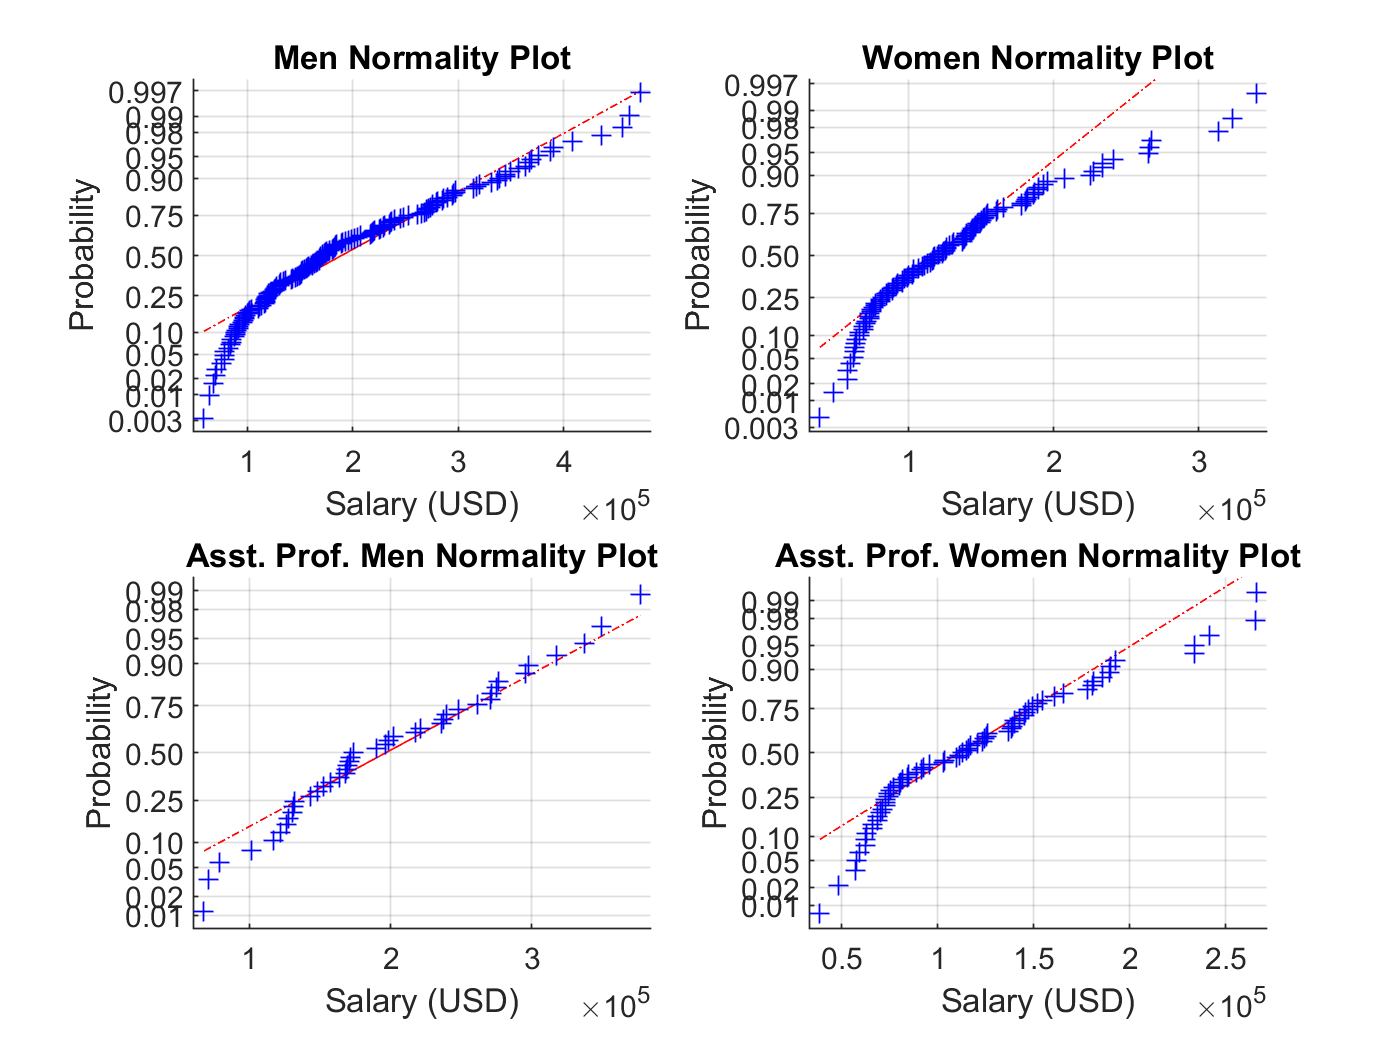

figure
subplot(2,2,1)
normplot(men) %quanlitative check
title('Men Normality Plot')
xlabel('Salary (USD)')

subplot(2,2,2)
normplot(women) %quanlitative check
title('Women Normality Plot')
xlabel('Salary (USD)')

subplot(2,2,3)
normplot(asstMen) %quanlitative check
title('Asst. Prof. Men Normality Plot')
xlabel('Salary (USD)')

subplot(2,2,4)
normplot(asstWomen) %quanlitative check
title('Asst. Prof. Women Normality Plot')
xlabel('Salary (USD)')

**Take Aways**

This normality plot shows that all 4 populations roughly follow a nonlinear regression line. It is likely one or more populations will not be normal when we run our AD Test.

%anderson-darling test for normality
% Ho: sample is normal, H1: sample is non-normal
[h1_norm(1),p1_norm(1), AD_stat(1), cv_norm(1)] = adtest(men);

[h1_norm(2),p1_norm(2), AD_stat(2), cv_norm(2)] = adtest(women);

[h1_norm(3),p1_norm(3), AD_stat(3), cv_norm(3)] = adtest(asstMen);
[h1_norm(4),p1_norm(4), AD_stat(4), cv_norm(4)] = adtest(asstWomen);

h1_norm

h1_norm = 1×4 logical array
   1   1   0   1


p1_norm

p1_norm =     0.0005    0.0005    0.2368    0.0006


### Decision

Step 7a) Decision : **Reject H0 for 3 of 4 groups**

7b) p = see above

7c) We have sufficient statistical evidence to infer that the 3 of the populations from which these data were randomly sampled may NOT be approximated by the Normal distribution. 

Based on n = (see below), the A-D tests are appropriate for this analysis.

n = [size(men,1) size(women,1) size(asstMen,1) size(asstWomen,1)]

n =    155   106    43    69


Multiple sample size variables are appropriate for this problem because all groups have different sample sizes.

**Take Aways:**

Most samples cannot be approximated by normal distribution. Non-parametric strategies must be used for further statistical analysis.

## TEST OF DIFFERENCE

For a 2 sample, independent, and non-parametric population, we have NO assumptions.

We only know the following:

- Random, Representative samples.

- All samples come from populations having the same continuous distribution.

- All observations are mutually independent.

Method: 2 Separate Mann-Whitney U Tests

Step 1 : (Note that a non-directional test is assumed.)

H0 : All populations are equal 

H1: All populations are not equal (at least two populations are statistically different in some way)

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make is 5%.

Step 3 : We will use the H statistic.

Step 4 : We do not have the information for the RSD or degrees of freedom because the data is non-parametric.

Step 5 : State the Critical Value for Rejecting the Null Hypothesis

    We will reject the null if the p-value < alpha

Step 6: Calculations

[p_asstMWU,h_asstMWU,stats_asstMWU] = ranksum(asstMen,asstWomen)

p_asstMWU = 8.8697e-08

h_asstMWU = logical
   1


stats_asstMWU = struct with fields:
       zval: 5.3485
    ranksum: 3324


[p_MWU,h_MWU,stats_MWU] = ranksum(men,women)

p_MWU = 4.2814e-09

h_MWU = logical
   1


stats_MWU = struct with fields:
       zval: 5.8729
    ranksum: 23823


### Decision

Step 7a) Decision : **Reject H0 for both tests**

7b) p < .001 (p less than alpha) for both tests

7c) We have sufficient statistical evidence to infer that population of men is statistically different from the population of women and the poulation of Assitant Professor men and the population of Assistent Professor women are statistically different.

7d) Appropriate Point Estimates (Salary in USD)

ds

ds = 4×6 table
                            Mean        SD         Med           Max         Min        IQR    
                         __________    _____    __________    __________    _____    __________

    Men                  1.9491e+05    94903    1.7097e+05    4.7259e+05    58923    1.3937e+05
    Women                1.3088e+05    62035    1.1914e+05    3.3966e+05    38675         72771
    Asst. Prof. Men      1.9784e+05    77196    1.7384e+05    3.7665e+05    67756    1.2341e+05
    Asst. Prof. Women     1.198e+05    54124    1.1284e+05    2.6586e+05    38675         73965


**Take Aways:** 

From our Mann-Whitney U tests, we know that both both sets of populations are statistically different, however, we do not have an indication of how they are different (location? shape? spread?). In the next section we will discuss how the populations differ.

## Discussion

Using the result of our Mann-Whitney U test, our point estimates, and our visual statistics, there are a few conclusions we can come to given certain assumptions. 

Assuming our locations are statistically different, we have sufficient statistical evidence to infer that men make a statistically different amount of money than women do on average, and the same can be said for the assitant professor populations, which have an even greater difference of means. This would mean that regardless of years on the job, men have a different salary on average. From our plots and point estimates we can see that this difference places men, regardless of years worked, making a higher salary on average.

Assuming our spreads are statistically different, we have sufficient statistical evidence to infer that men have a statistically different range of salaries than women do, and the same can be said for the assistan professor populations, which have smaller ranges than the overall populations of men and women. From our plots and point esitmates, we can see that the women, having lower salaries on average, may be getting lower initial salaries and then have less opportunities for or simply smaller raises than those of the men populations.

Assuming our shapes are statistically different, we have sufficient statistical evidence to infer that men have more of a skewedness towards higher salaries than women do, regarless of years worked on the job. This indicates that men have the opportunity to make a higher salary than women do as their salary ceilings are higher regardless of years worked.

## Cents to the Dollar

Seeing that women seem to make less than men in the same profession regardless of years worked. Let's use the means of the populations to find how much women make compared to men in the form of cents to the dollar.

centsToTheDollar = mean(women)/mean(men)

centsToTheDollar = 0.6715

## Conclusion

From all of our statistical analysis, including our visual plots, point estimates, and our infferential statistics, it is clear that men and women make different salaries, and from the Mann-Whitney U test, the most likely differences in the populations is in location and in shape. With this assumption, we can see that not only do women make less money than men on average regardless of years worked (specifically about $0.67 to the dollar), but, women also have either less raises than men, or their raises are smaller than men, regardless of years worked. This shows that we have enough sufficient statistical evidence to infer that women are discriminated against in the form of pay discrimination in this particular workplace of the Housten College of Medicine. More data would be needed to find out if this same discrimination happens on a national scale.